[audio, fs] = audioread('long_tailed_tit.flac');

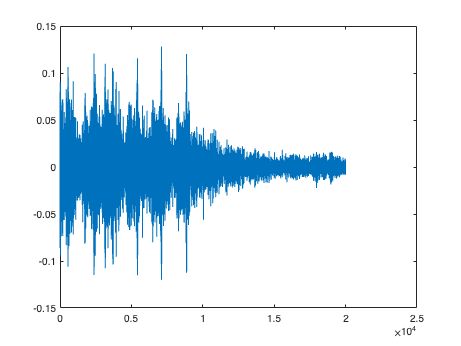

x = audio(2e4:4e4);
plot(x);

[~,delta,deltaDelta,loc] = mfcc(x, fs);

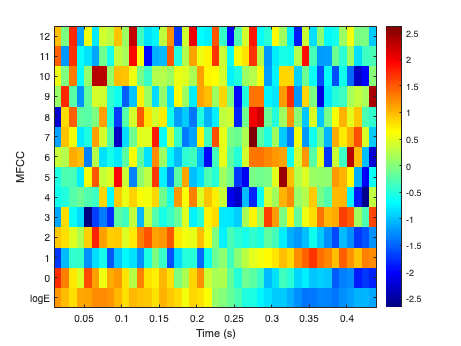

mfcc(x, fs)

% check what the limits mean

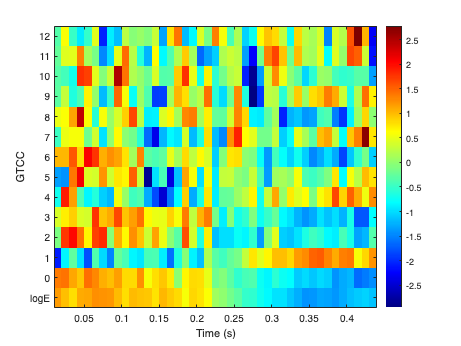

gtcc(x, fs)

**Extracting MFCC from Frequency-Domain audio**

win = hann(1024,"periodic");
S = stft(x,"Window",win,"OverlapLength",512,"Centered",false);

coeffs = mfcc(S,fs,"LogEnergy","Ignore");

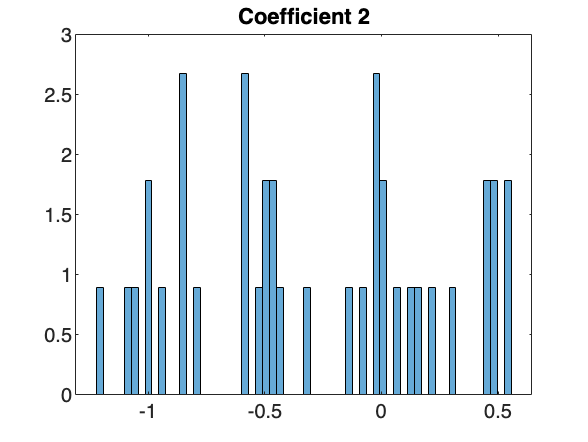

nbins = 60;
coefficientToAnalyze = 2;

histogram(coeffs(:,coefficientToAnalyze+1),nbins,"Normalization","pdf")
title(sprintf("Coefficient %d",coefficientToAnalyze))